a = 0; 
b = 14;
x = linspace(a,b,500)

x =          0    0.0281    0.0561    0.0842    0.1122    0.1403    0.1683    0.1964    0.2244    0.2525    0.2806    0.3086    0.3367    0.3647    0.3928    0.4208    0.4489    0.4770    0.5050    0.5331    0.5611    0.5892    0.6172    0.6453    0.6733    0.7014    0.7295    0.7575    0.7856    0.8136    0.8417    0.8697    0.8978    0.9259    0.9539    0.9820    1.0100    1.0381    1.0661    1.0942    1.1222    1.1503    1.1784    1.2064    1.2345    1.2625    1.2906    1.3186    1.3467    1.3747


h = 0.001; 
iter=1000; 
eps=0.001;
f=@(x)sin(x)./x;
y=f(x);
plot(x,f(x),x,0*x,':'); 
grid on
xlabel('x'); 
ylabel('y')
hold on
ymin=min(y); 
ymax=max(y);
if ymin<0 ymin=1.1*ymin; 
else ymin=0.9*ymin; 
end;
if ymax>0 ymax=1.1*ymax; 
else ymax=0.9*ymax; 
end;
axis([a,b,ymin,ymax]);
z = ginput(2); 
z1=z(1,1), 

z1 = 1.7145

z2=z(2,1);
f1 = f(z1); 
f2=f(z2); 
z=(z1+z2)/2; 
y=f(z);
P = plot(z1,0,'*',z2,0,'*',z,0,'o');
if f1*f2>0 'Плохие точки'
end;
for i=1:iter
z=(z1+z2)/2; y=f(z);
delete(P);
P=plot(z1,0,'*',z2,0,'*',z,0,'o');
if y*f1<0
z2=z;
else z1=z;
end;
if abs(f(z))<eps
break;
end;
end;
disp("Найденный корень " + z);

Найденный корень 3.1415


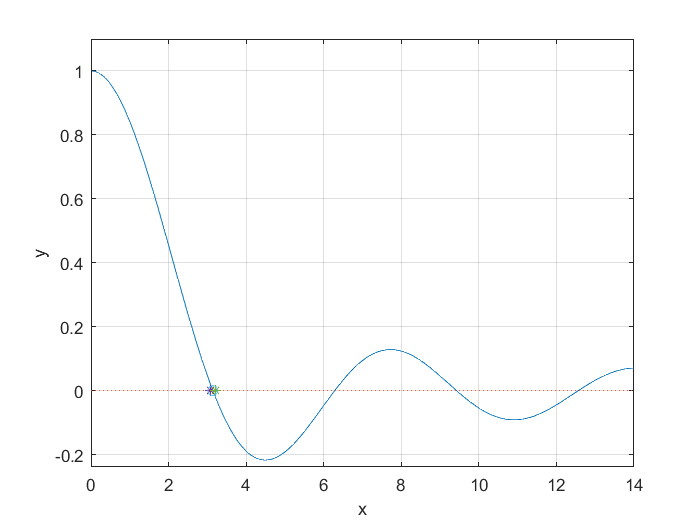

hold off